# 802.11ac SEM (dB scale)

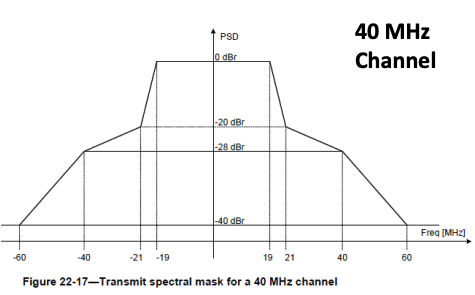

### Normalized frequency $f\in [-0.5, 0.5]$


$$f \text{(cycles/sample)} = \frac{F\text{(cycles/sec)}}{ F_s\text{(sampling rate)}} = \frac{F}{2B\text{(bandwidth)}}$$


### Definition of the 802.11ac SEM function in $F$ (MHz)


$$\mathrm{SEM}(F) = \left\{\begin{array}{ll}
0 & \mbox{if } 0\leq |F| \leq 19\\
-10 |F| + 190 & \mbox{if } 19\leq |F| \leq 21\\
-\frac{8}{19} |F| +(\frac{168}{19}-20) & \mbox{if } 21\leq |F| \leq 40\\
-\frac{3}{5} |F| - 4 & \mbox{if } 40\leq |F| \leq 60\\
-40 & \mbox{if } |F| \geq 60\\
\end{array}\right.$$


### Definition of the 802.11ac SEM in $f, B$ (MHz)


$$\mathrm{SEM}(f, B) = \left\{\begin{array}{ll}
0 & \mbox{if } 0\leq |f| \leq \frac{19}{2B}\\
-10 \cdot 2B\cdot |f| + 190 & \mbox{if } \frac{19}{2B}\leq |f| \leq \frac{21}{2B}\\
-\frac{8}{19}\cdot 2B\cdot |f| +(\frac{168}{19}-20) & \mbox{if } \frac{21}{2B}\leq |f| \leq \frac{40}{2B}\\
-\frac{3}{5}\cdot 2B\cdot |f| - 4 & \mbox{if } \frac{40}{2B}\leq |f| \leq \frac{60}{2B}\\
-40 & \mbox{if } |f| \geq \frac{60}{2B}\\
\end{array}\right.$$


function SEM = ac(delta_f, f_range, B)
    % Generate only the positive part
    f = f_range(1):delta_f:f_range(2);
    SEM = zeros(length(f), 1);
    
    W = 2*B;
        
    for idx = 1:length(f)
        if f(idx) < 19/W
            % freq: 0~19 MHz
            SEM(idx) = 0;
        elseif f(idx) < 21/W
            % freq: 19~21 MHz
            SEM(idx) = -10 * (f(idx)*W) + 190;
        elseif f(idx) < 40/W
            % freq: 21~40 MHz
            SEM(idx) = -0.4211 * (f(idx)*W) + (168/19 - 20);
        elseif f(idx) < 60/W
            % freq: 40~60 MHz
            SEM(idx) = -0.6 * (f(idx)*W) - 4;
        else
            % freq: >60 MHz
            SEM(idx) = -40;
        end
    end
    
     % Generate the negative part
     SEM = [flipud(SEM); SEM(2:end)];
end